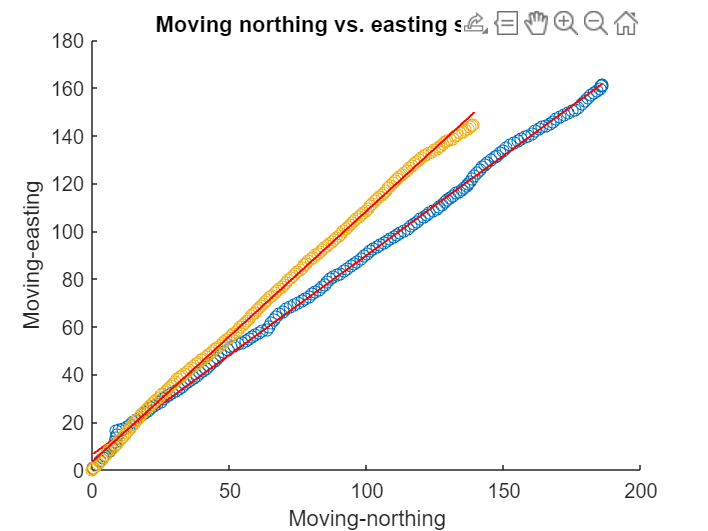

file_path1 = 'C:\Users\gajapathy.s\Desktop\gps\gps_occ_walking.bag';
file_path2 = 'C:\Users\gajapathy.s\Desktop\gps\bag_sri_walking.bag';



 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);
 scatterplot(UE,UN);
 
   p = polyfit(UE, UN, 1);

    y_fit = polyval(p, UE);


    hold on;
    plot(UE, y_fit, 'r-', 'LineWidth', 1, 'DisplayName', 'Line of Best Fit');
    hold off;


  hold on
 
  [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= ex_bag(file_path2);
  scatterplot(UE,UN);
    p = polyfit(UE, UN, 1);

    y_fit = polyval(p, UE);


    hold on;
    plot(UE, y_fit, 'r-', 'LineWidth', 1, 'DisplayName', 'Line of Best Fit');
    hold off;

xlabel('Moving-northing');
ylabel('Moving-easting');
title('Moving northing vs. easting scatterplots');
% legend('Occluded walking ','Open walking')
hold off

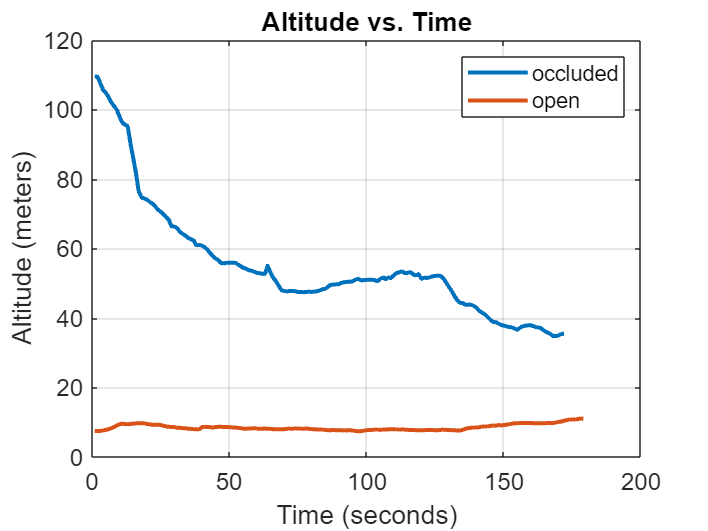


alt(file_path1,file_path2)

function []= alt(file_path1,file_path2)
 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);
 altitude_(Alt,delta_time);
 hold on
  [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= ex_bag(file_path2);
 altitude_(Alt,delta_time);

function[]= altitude_(Alt,delta_time)

t = 1:1:delta_time;

plot(t, Alt,"LineWidth",2.0 ); 

xlabel('Time (seconds)');
ylabel('Altitude (meters)');
title('Altitude vs. Time');
legend("occluded","open")

grid on;

set(gca, 'FontName', 'Arial', 'FontSize', 12);
set(gcf, 'Color', 'w'); 

end
end


function []=scatterplot(UE,UN,c)
scatter(UE, UN);
end




function [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1)
Alt=0;
lat=0;
long=0;
Alt=0;
UtmE=0;
UtmN=0;
delta_time=0;

bag = rosbag(file_path1);
bSel = select(bag,'Topic','/chatter');
msgStructs = readMessages(bSel,'DataFormat','struct');

len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;

for i=1:1:len
gps=msgStructs{i};
lat(i)=gps.Latitude;
long(i)=gps.Longitude;
Alt(i)=gps.Altitude;
UtmE(i)=gps.UtmEasting;
UtmN(i)=gps.UtmNorthing;

 UE(i)=UtmE(i)-UtmE(1);
 UN(i)=UtmN(i)-UtmN(1);

Z=gps.Zone;
L=gps.Letter;
H=gps.Hdop;
latD=gps.LatitudeDir;
lonD=gps.LongitudeDir;

end

end




function [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= ex_bag(file_path2)

bag = rosbag(file_path2);
bSel = select(bag,'Topic','/wire');
msgStructs = readMessages(bSel,'DataFormat','struct');
len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;


for i=1:1:len
gps=msgStructs{i};
lat(i)=gps.Lat;
long(i)=gps.Lon;
Alt(i)=gps.Alt;
UtmE(i)=gps.UtmEasting;
UtmN(i)=gps.UtmNorthing;
 UE(i)=UtmE(i)-UtmE(1);
 UN(i)=UtmN(i)-UtmN(1);

Z=gps.Zone;
L=gps.Letter;
H=gps.Hdop;

end


end

















































